# Finite Difference Method

## CP2a

Betingelsene fra 8.2.2a)


$$u_{tt} = 16u_{xx} \\
u(x,0) = \sin \pi x \text{ for } 0 \le x \le 1 \\
u_t(x,0) = 0 \text{ for } 0 \le x \le 1 \\
u(0,t) = 0 \text{ for } 0 \le t \le 1 \\
u(1,t) = 0 \text{ for } 0 \le t \le 1$$


Dette gir at $c = \sqrt{4} = 2$, $g(x) = 2\pi \sin \pi x$, $f(x)=l(x)=r(x)=0$

c = 2;
g = @(x) 1*pi*sin(pi*x);
f = @(x) x*0;
l = f;
r = f;

Skal løses med $h = 0.05$ og en $k$ som tilfredsstiller $\sigma = \frac{ck}{h} \le 1$ – altså med $\frac{2\cdot k}{0.05} = 2\cdot20\cdot k = 40k \le 1 \Rightarrow k \le \frac{1}{40}$

**MEN HVORFOR ER k <= 0.05 eller noe det faktiske kriteriet?**

h = 0.05;
M = 1/h;
k = 1/40;
N = 1/k;

Så, med $k = 1/40$:

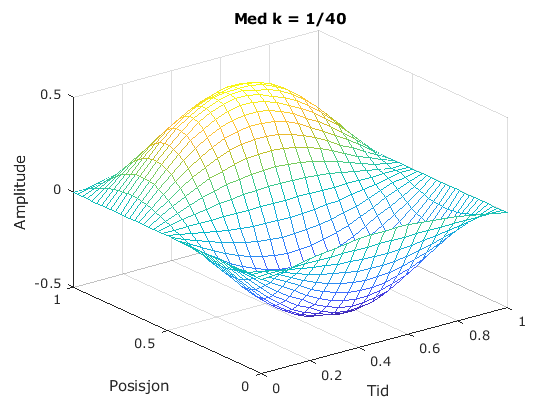

finiteDfference(0, 1, 1, M, N, c, f, g, l, r);
title("Med k = 1/40")

Med $k = 1/20 > 1/40
$ ser vi at det er litt dårligere stilt:

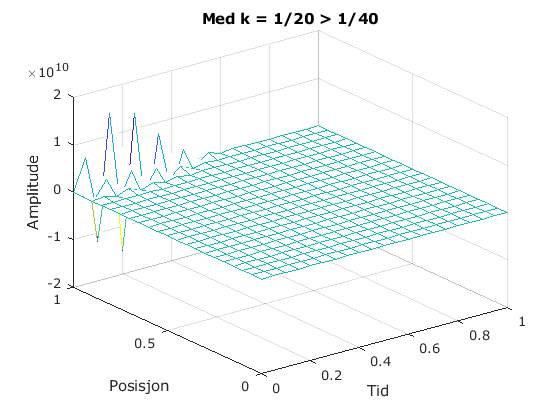

finiteDfference(0, 1, 1, M, 20, c, f, g, l, r);
title("Med k = 1/20 > 1/40")

function finiteDfference(a, b, T, M, N, c, f, g, l, r)
%FINITEDIFFERENCE Finite Difference Method for the wave equation
%   Løser  u_tt = c² u_xx  numerisk
%   a og b er grensebetingelsene u(a,t)=l(t) og u(b,t)=r(t)
%   T utgjør høyre grense i tidsintervallet [0,T]
%   f(x) er initialbetingelsen for u(x,a)
%   g(x) er initialbetingelsen for u_t(x,a)
%   c er en bølgefartparameteren til den originale likningen
%   M og N er antall samplinger langs x- og t-aksen
%   NB: f, g, l og r er funksjoner

    % Beregner steglengder og sigma
    h = (b-a)/M;
    k = T/N;
    sigma = c*k / h;
    m = M-1;
    
    % Setter opp aksene
    x = linspace(a,b,M)';
    t = linspace(0,T,N+1);
    
    % Lager diagonalmatrisen A
    e = ones(m, 1);
    A = spdiags([sigma*e, (2-2*sigma)*e, sigma*e], [-1,0,1], m, m);

    % Lager kolonne 1 i w basert på initialbetingelsene
    w = zeros(m,N);
    s = 1/2 * sigma^2 * [l(0) zeros(1,m-2) r(T)]';
    w(:,1) = 1/2 * A * f(x(1:m)) + k*g(x(1:m)) + s;
    
    % Regner ut resten av w
    for j = 2:N
        % s = sigma*[l(j*k) zeros(1,m-2) r(j*k)]';
        w(:,j+1) = A * w(:,j) - w(:,j-1) + sigma^2 * [l(j*k) zeros(1,m-2) r(j*k)]';
    end
    
    w = [l(t); w; r(t)];

    [X,T] = meshgrid(linspace(a,b,M+1)',t);
    mesh(X,T,w')
    xlabel('Tid')
    ylabel('Posisjon')
    zlabel('Amplitude')
end